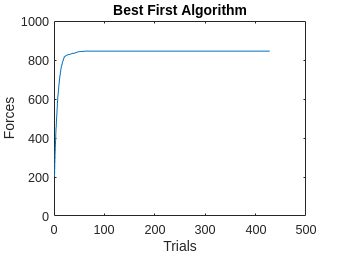

% Creating Patients' Corticalspinal cells.
% Patient 1 - Severely Impaired
% Patient 2 - Moderately Impaired
n = 1000;

% Initalize the base CS cells
x_0 = rand(1, n);

% Parameters for zero-mean normal distribution
std_dev = 0.04;
mean = 0;

% CS extensor and flexor connection weights
flexor_c_w = create_cs(0.7, n);
extensor_c_w = create_cs(0.3, n);

% Translating MN pool to force
delta = 1;

final_forces = [];
trials = [];
f_final_net = 0;

normal_therapy = normal_therapy();

for day_i = 1:length(normal_therapy)
    day = normal_therapy(day_i);
    for trial = 1:day
        v_i = std_dev.*randn(1, n) + mean;
        x_i = x_0 + v_i;
    
        % Flexor MN Pools translated to force
        s_fi = 0;
        for i = 1:n
            s_fi = s_fi + g_i(x_i(i), flexor_c_w(i));
            % s_fi = s_fi + x_i(i) * c_fi(i);
        end
        f_f = delta * s_fi;
        
        % Extensor MN Pools translated to force
        s_ei = 0;
        for i = 1:n
            s_ei = s_ei +  g_i(x_i(i), extensor_c_w(i));
            % s_ei = s_ei + x_i(i) * c_ei(i);
        end
        f_e = delta * s_ei;
    
        % Net force
        f_net = f_f - f_e;
    
        if f_net > f_final_net
            f_final_net = f_net;
            x_0 = x_i;
        end
    end
   
    % forces = [forces, f_net];
    final_forces = [final_forces, f_final_net];
end

% plot(trials, forces, trials, final_forces)
plot(final_forces)
title("Best First Algorithm")
ylim([0, n])
ylabel('Forces')
xlabel('Trials')

saveas(gcf,'images/BestFirstAlgo.png')